# Developed Nests Architecture Description

load('Data\DevNests.mat')



% create tables for 3 structure classes
S1 = struct('Class',[]);
for i=1:3
    T = table;
    for j=1:length(S)
        if S(j).Data(i).TotalArea == 0
            T{j,:} = zeros(1,16);
        else
            T(j,:) = struct2table(S(j).Data(i));
        end
    end
    S1(i).Class = T;
end
S1(3).Class.Properties.VariableNames = S1(2).Class.Properties.VariableNames;

## Find mean area, width and orient for each class

AreaMeans = table;
for i=1:3
    AreaMeans.N(i) = sum(S1(i).Class.NumOfBlubs);
    AreaMeans.mean(i) = sum(S1(i).Class.MeanArea.*S1(i).Class.NumOfBlubs)./AreaMeans.N(i);
    AreaMeans.STD(i) = std(S1(i).Class.MeanArea,S1(i).Class.NumOfBlubs);
    AreaMeans.SEM(i) = AreaMeans.STD(i)./sqrt(AreaMeans.N(i));
end

WidthMeans = table;
for i=1:3
   WidthMeans.TotalLength(i) = sum(S1(i).Class.SkelLength);
    WidthMeans.mean(i) = sum(S1(i).Class.MeanWidth.*S1(i).Class.SkelLength)./WidthMeans.TotalLength(i);
    WidthMeans.STD(i) = std(S1(i).Class.MeanWidth,S1(i).Class.SkelLength);
    WidthMeans.SEM(i) = WidthMeans.STD(i)./sqrt(WidthMeans.TotalLength(i));
end

WidthMeansB = table;
for i=1:3
   WidthMeansB.N(i) = sum(S1(i).Class.NumOfBlubs);
   WidthMeansB.mean(i) = sum(S1(i).Class.MeanWidth.*S1(i).Class.NumOfBlubs)./WidthMeansB.N(i);
   WidthMeansB.STD(i) = std(S1(i).Class.MeanWidth,S1(i).Class.NumOfBlubs);
   WidthMeansB.SEM(i) = WidthMeansB.STD(i)./sqrt(WidthMeansB.N(i));
end
% OrientMeans = table; %% DONT USE normalized on blubs and not on length, gives much lower angles
% for i=1:3
%     OrientMeans.N(i) = sum(S1(i).Class.NumOfBlubs);
%     OrientMeans.mean(i) = sum(S1(i).Class.MeanOrientation.*S1(i).Class.NumOfBlubs)./OrientMeans.N(i);
%     OrientMeans.STD(i) = std(S1(i).Class.MeanOrientation,S1(i).Class.NumOfBlubs);
%     OrientMeans.SEM(i) = OrientMeans.STD(i)./sqrt(OrientMeans.N(i));
% end

AngleMeans = table; % normalized on length, better
for i=1:3
    AngleMeans.TotalLength(i) = sum(S1(i).Class.SkelLength);
    AngleMeans.mean(i) = sum(S1(i).Class.MeanAngle.*S1(i).Class.SkelLength)./AngleMeans.TotalLength(i);
    AngleMeans.STD(i) = std(S1(i).Class.MeanAngle,S1(i).Class.SkelLength);
    AngleMeans.SEM(i) = AngleMeans.STD(i)./sqrt(AngleMeans.TotalLength(i));
end

## Find area ratios between classes

AreaRatio = table;
for j=1:length(S)
    AreaRatio.Total(j) = sum([S(j).Data.TotalArea]);
    AreaRatio.Tunnels(j) = S(j).Data(1).TotalArea./AreaRatio.Total(j);
    AreaRatio.ChambersS(j) = S(j).Data(2).TotalArea./AreaRatio.Total(j);
    AreaRatio.ChambersL(j) = S(j).Data(3).TotalArea./AreaRatio.Total(j);
end


disp('Area')

Area


for i=1:3
    disp(AreaRatio.Properties.VariableNames{i+1})
    disp('mean')
    mean(AreaRatio{:,i+1})
    disp('sd')
    std(AreaRatio{:,i+1})
end

Tunnels


mean


ans = 0.1883

sd


ans = 0.1046

ChambersS


mean


ans = 0.3607

sd


ans = 0.2095

ChambersL


mean


ans = 0.4511

sd


ans = 0.2609


LengthRatio = table;
for j=1:length(S)
    LengthRatio.Total(j) = sum([S(j).Data.SkelLength]);
    LengthRatio.Tunnels(j) = S(j).Data(1).SkelLength./LengthRatio.Total(j);
    LengthRatio.ChambersS(j) = S(j).Data(2).SkelLength./LengthRatio.Total(j);
    LengthRatio.ChambersL(j) = S(j).Data(3).SkelLength./LengthRatio.Total(j);
end


disp('Length')

Length


for i=1:3
    disp(LengthRatio.Properties.VariableNames{i+1})
    disp('mean')
    mean(LengthRatio{:,i+1})
    disp('sd')
    std(LengthRatio{:,i+1})
end

Tunnels


mean


ans = single
0.3269

sd


ans = single
0.1410

ChambersS


mean


ans = single
0.3288

sd


ans = single
0.1625

ChambersL


mean


ans = single
0.3443

sd


ans = single
0.2286

**Create figure of 3 images and their structure segmentation**

**use from DevNests: F3,F4 & F29**

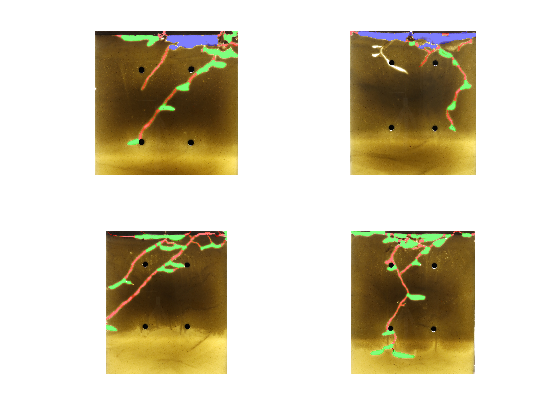

set = imageSet(uigetdir);


for i=1:set.Count
    figure
    string = strsplit(set.ImageLocation{i},{'\','.'});
    filename = string{end-1};
    string = strsplit(filename,'_');
    tag = string{1};
    Arch = imread(set.ImageLocation{i});
    Arch = imresize(Arch,0.25);
    load(['Data\Graphics\',tag,'\',filename,'.mat'],'Zf');
   % Zf = imresize(Zf,4);
%     Z1 = zeros(size(Zf,1),size(Zf,2),3);
%     for j=1:3
%         Z1(:,:,j)=Z==j;
%     end
    RED = cat(3,ones(size(Zf)),zeros(size(Zf)), zeros(size(Zf)));
    GREEN = cat(3,zeros(size(Zf)),ones(size(Zf)), zeros(size(Zf)));
    BLUE = cat(3,zeros(size(Zf)),zeros(size(Zf)), ones(size(Zf)));
    RGB = cat(4,RED, GREEN, BLUE);
    
    imshow(Arch)
    hold on
    for j=1:3
        h = imshow(RGB(:,:,:,j));
        AlphaMap = uint8(round(0.5*255).*(Zf==j));
        alpha(h,AlphaMap)
    end
end